close all
clear
clc

clc
M = 128; % signal dimension
N = M; % nr of atoms in the basis (this will be different when using redundant set of generators)

DCT = nan(M, N); % matrix containing the standard basis (a kronecker delta in each column)
D = nan(M, N); % matrix containing the DCT basis (a DCT function in each column)

## generate 1D DCT basis (DCT type II)

disp('generatin2g 1-D DCT basis')

generatin2g 1-D DCT basis


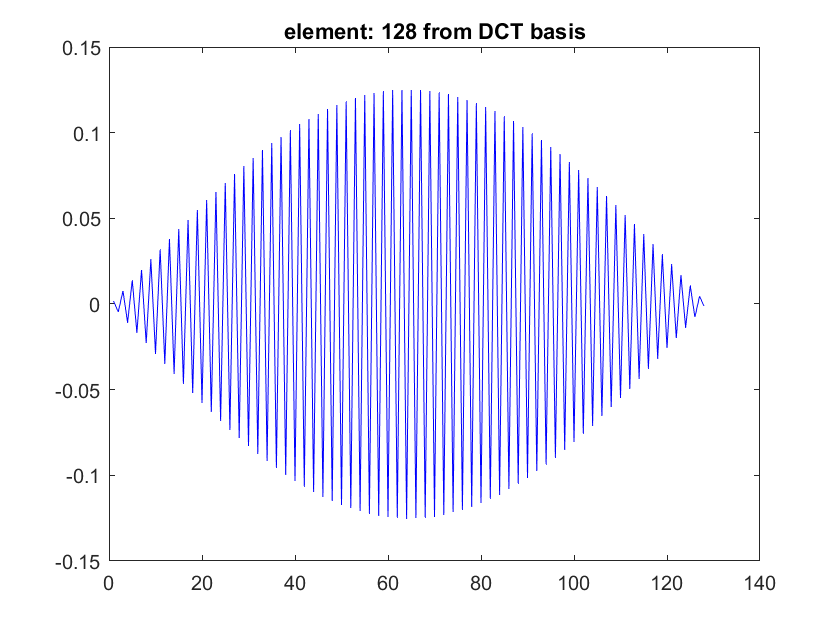


for k = 1 : M
    % take the formula from slides and remember to normalize. Each atom
    % goes in a column of DCT matrix
    if k == 1
        ck = sqrt(1/N);
    else
        ck = sqrt(2/N);
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%% Check what is L
    v = linspace(0,M-1, M);
    DCT(:, k) = ck * cos((k-1) * pi * (2*v + 1)/(2*M));

    % display the atom
    figure(51), plot(DCT(:, k), 'b-')
    title(['element: ', num2str(k) ' from DCT basis']);

end

% check orthogonality
is_DCT_orth = isequal(transpose(DCT)*DCT, eye(128))

is_DCT_orth = logical
   0


(DCT)

DCT =     0.0884    0.1250    0.1250    0.1249    0.1248    0.1248    0.1247    0.1245    0.1244    0.1242    0.1241    0.1239    0.1236    0.1234    0.1232    0.1229    0.1226    0.1223    0.1220    0.1216    0.1213    0.1209    0.1205    0.1201    0.1196    0.1192    0.1187    0.1182    0.1177    0.1172    0.1166    0.1161    0.1155    0.1149    0.1143    0.1136    0.1130    0.1123    0.1117    0.1110    0.1102    0.1095    0.1088    0.1080    0.1072    0.1064    0.1056    0.1048    0.1039    0.1031
    0.0884    0.1249    0.1247    0.1242    0.1236    0.1229    0.1220    0.1209    0.1196    0.1182    0.1166    0.1149    0.1130    0.1110    0.1088    0.1064    0.1039    0.1013    0.0985    0.0956    0.0926    0.0895    0.0862    0.0828    0.0793    0.0757    0.0720    0.0682    0.0643    0.0603    0.0562    0.0521    0.0478    0.0436    0.0392    0.0348    0.0304    0.0259    0.0214    0.0168    0.0123    0.0077    0.0031   -0.0015   -0.0061   -0.0107   -0.0153   -0.0199   -0.0244   

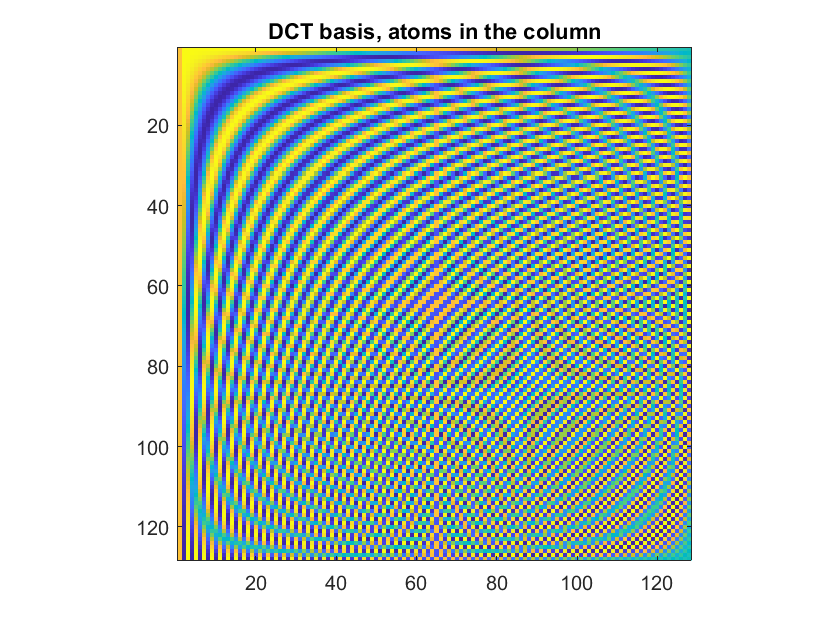

% display the basis in the matrix
figure(3), imagesc(DCT), title('DCT basis, atoms in the column'), axis equal, axis tight

## generate 1D DCT basis using the function idct which is the inverse dct transform

stack this in the matrix D

for k = 1 : M
    % define the atom
    a = zeros(1, M);
    a(k) = 1;
    D(:, k) = idct(a)';
end
% display the basis in the matrix
figure(3), imagesc(D), title('DCT basis, atoms in the column'), axis equal, axis tight


% check that D and DCT defined above coincide
is_DCT_equal_D = isequal(D, DCT)

is_DCT_equal_D = logical
   0


% check orthogonality
is_D_orth = isequal(transpose(D)*D, eye(128))

is_D_orth = logical
   0


## Analysis: compute the representation of an input ECG signal

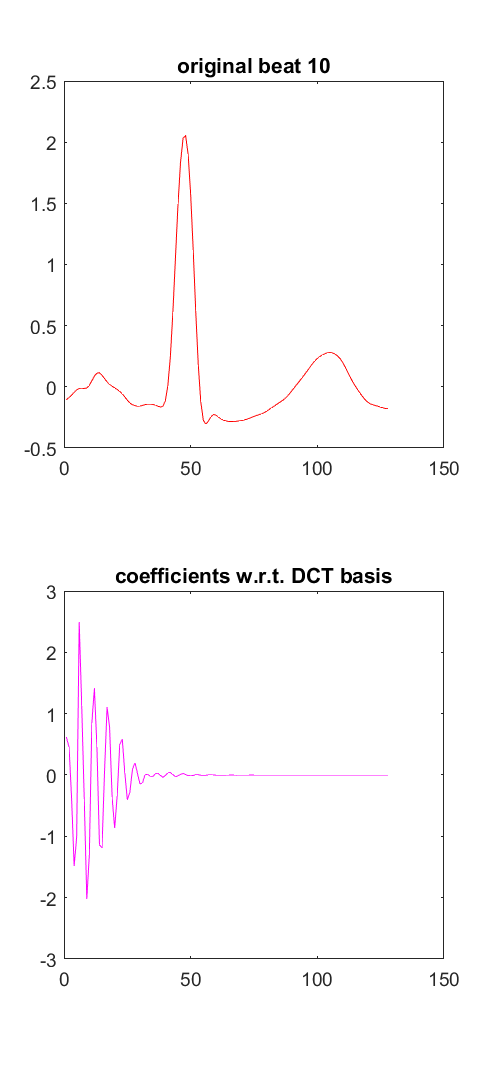

% load few ECG signals to be processed
temp = load('C:\Users\simo9\Desktop\MMMIP\lez1_A_orth_basis\croppedECG.mat'); 
nBeats = 10;
S = temp.S(:, 1 : nBeats);
coeff_D = nan(M, nBeats); % nitialize the matrix of representations of S w.r.t. D

% display the signal and the representation coefficients
for ii = 1 : size(S, 2)
    
    % compute the representation of each beat w.r.t. the two basis 
    coeff_D(:, ii) = transpose(D) * S(:,ii);
    %%%%%%checkkk
    figure(5)
    subplot(2,1,1)
    plot(S(:, ii), 'r'), title(['original beat ', num2str(ii)]);
    subplot(2,1,2)
    plot(coeff_D(:, ii), 'm'), title('coefficients w.r.t. DCT basis');
    pause(0.2)
    set(gcf, 'Position', [680   2   372   815])
    %     disp('hit a key')
    %     pause()
end

## Synthesis: reconstruct all the ECG signals from their representations

% reconstruct the two signals (express them w.r.t. the standar dbasis)
S_hat_D = (D) * coeff_D

S_hat_D =    -0.1400   -0.1227   -0.1340   -0.1303   -0.1319   -0.1364   -0.1576   -0.1235   -0.1424   -0.1035
   -0.1276   -0.1187   -0.1289   -0.1116   -0.1265   -0.1323   -0.1419   -0.1122   -0.1321   -0.0874
   -0.1079   -0.1059   -0.1159   -0.0916   -0.1148   -0.1134   -0.1149   -0.0956   -0.1120   -0.0672
   -0.0857   -0.0849   -0.0972   -0.0726   -0.0966   -0.0791   -0.0856   -0.0766   -0.0842   -0.0449
   -0.0676   -0.0591   -0.0767   -0.0563   -0.0742   -0.0421   -0.0627   -0.0601   -0.0564   -0.0249
   -0.0562   -0.0342   -0.0569   -0.0456   -0.0519   -0.0177   -0.0474   -0.0490   -0.0365   -0.0127
   -0.0491   -0.0172   -0.0417   -0.0443   -0.0351   -0.0098   -0.0390   -0.0424   -0.0266   -0.0108
   -0.0441   -0.0126   -0.0354   -0.0510   -0.0279   -0.0124   -0.0385   -0.0381   -0.0233   -0.0136
   -0.0401   -0.0161   -0.0360   -0.0556   -0.0286   -0.0183   -0.0425   -0.0326   -0.0202   -0.0090
   -0.0316   -0.0153   -0.0323   -0.0447   -0.0281   -0.0189   -0.0396   -0.0197 


% check if there is perfect reconstruction
% trivial because S_hat_D = D * D' * S and D * D' = eye(M)  since D is orthonormal basis (the same applies to C)
disp('perfect reconstruction?')

perfect reconstruction?


is_reconstruction_perfect = isequal(S_hat_D, S)

is_reconstruction_perfect = logical
   0


## Add noise to ECG data and inspect the representations

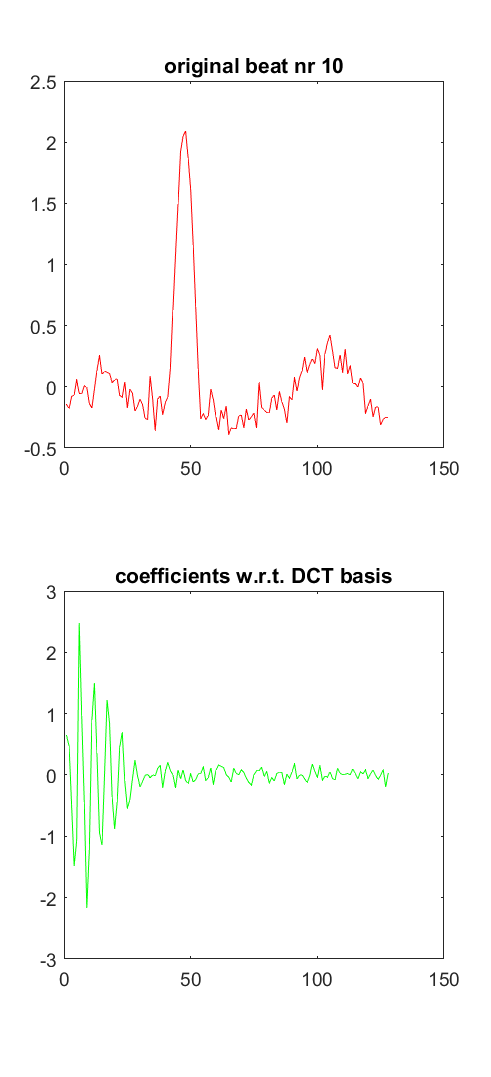

% add AWGN noise to ECG signals
nBeats = 10;    
temp = load('croppedECG.mat'); % load few ECG signals to be processed
S0 = temp.S(:, 1 : nBeats);

sigma_noise = 0.1;
S = S0 + sigma_noise * randn(size(S0));

coeff_D = nan(M, nBeats); % nitialize the matrix of representations of S w.r.t. D

% display the signal and the representation coefficients
for ii = 1 : size(S, 2)
    
    % compute the representation of each beat w.r.t. the two basis 
    coeff_D(:, ii) = transpose(D) * S(:,ii);
    
    figure(5)
    subplot(2,1,1)
    plot(S(:, ii), 'r'), title(['original beat nr ', num2str(ii)]);
    subplot(2,1,2)
    plot(coeff_D(:, ii), 'g'), title('coefficients w.r.t. DCT basis');
    set(gcf, 'Position',  [680   2   372   815])
    drawnow
    pause(0.05)
    
    % disp('hit a key')
    % pause()
end

## Hard thresholding

noise affects all the coefficients of our transformation keep only few coefficients having largest magnitude

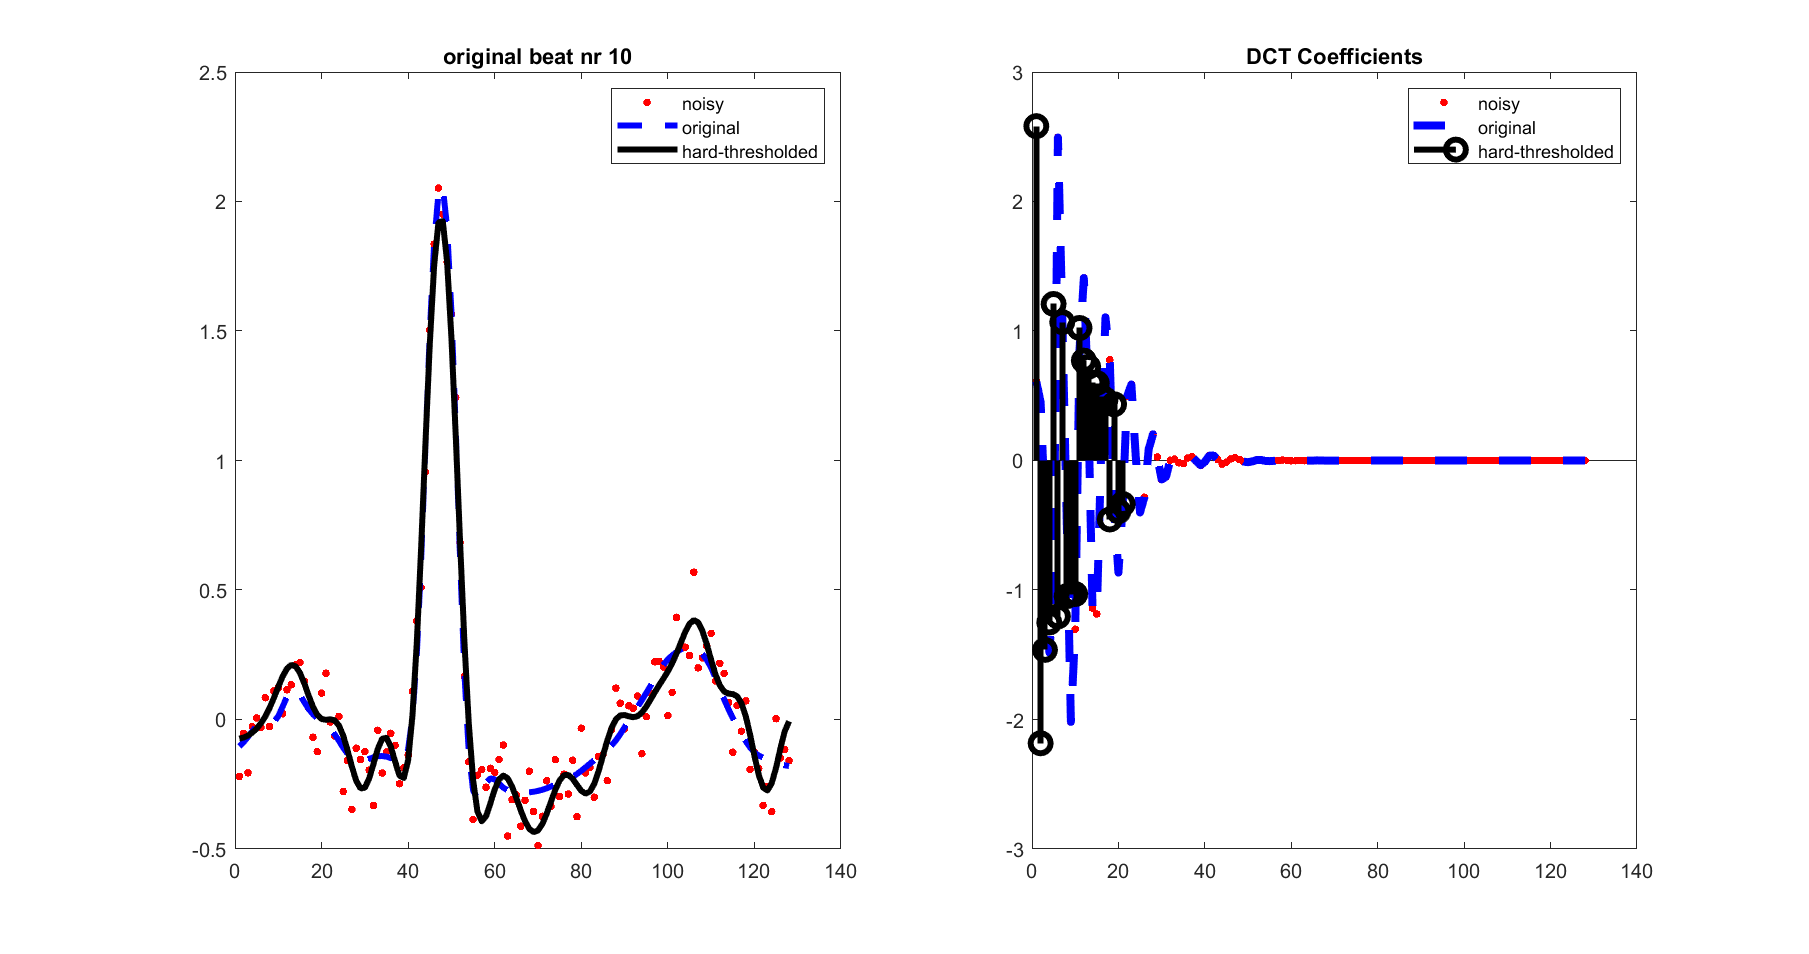

% add AWGN noise to ECG signals
nBeats = 10;
temp = load('croppedECG.mat'); % load few ECG signals to be processed
S0 = temp.S(:, 1 : nBeats);
sigma_noise = 0.1;

% add noise
S = S0 + sigma_noise * randn(size(S0));

L = 21; % sparsity level (try different values) size(S, 1)

for ii = 1 : 10 %nBeats
    
    origSignal = S0(:,ii);
    noisySignal = S(:,ii);
    
    % transform each signal separately (analysis) 
    coeff_or = transpose(D) * origSignal;
    coeff_no = transpose(D) * noisySignal;
    
    % keep only the L largest coefficients (absolute value)
    % [...]
    [~, argcoeff_HT] = maxk(abs(coeff_no), L);
    coeff_HT = coeff_no(argcoeff_HT);
    % invert the transformation
    s_hat = D(:,argcoeff_HT)*coeff_HT;
    
    LN_WDT = 3;
    MRK_SZ = 10;
    
    % show the signals
    figure(5)
    subplot(1,2,1)
    plot(noisySignal, 'r.', 'MarkerSize', MRK_SZ), 
    hold on
    plot(origSignal, 'b--', 'LineWidth', LN_WDT),  
    plot(s_hat, 'k-', 'LineWidth', LN_WDT),
    title(['original beat nr ', num2str(ii)]);
    hold off
    legend('noisy', 'original', 'hard-thresholded')
    
    subplot(1,2,2)
    plot(coeff_or, 'r.', 'MarkerSize', MRK_SZ), 
    hold on
    % coefficients of the noise free signal
    plot(D' * origSignal, 'b--', 'LineWidth', LN_WDT + 1),  
    stem(find((coeff_HT ~= 0)), coeff_HT(coeff_HT ~= 0), 'k-', 'LineWidth', LN_WDT, 'MarkerSize', MRK_SZ),  
    title('DCT Coefficients')
    hold off
    legend('noisy', 'original', 'hard-thresholded')

    set(gcf, 'Position', [423        97        1206         636])

    pause(0.05)
    % disp('hit a key')
    % pause()
end